load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
% lateralSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-disagree, 1-agree
% orderSheet= zeros(Delta_e_steps, Delta_i_steps); % -1-NaN, 0-disagree, 1-agree
% gammaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noGamma, XX-frequency
% betaSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, 0-noBeta, XX-frequency
% ratioSheet = zeros(Delta_e_steps, Delta_i_steps,5); % -1-NaN, X-ratio
% osciSheet = zeros(Delta_e_steps, Delta_i_steps,5,2); % -1-NaN, 0-noOsci, 1-hasOsci; before and after

% agree = orderSheet == 3;
% disagree = orderSheet == 1 | orderSheet == 2;
% orderSheet(agree) = 1;
% orderSheet(disagree) = 0;
% orderSheet = flip(orderSheet');

Delta_e_start = 0; % cannot equal to 0
Delta_e_end = 0.5; % can equal to 0.5

Delta_i_start = 0; % cannot equal to 0
Delta_i_end = 0.05; % can equal to 0.05
steps = 100;

Iattn = 0.02;

n = 1:100;
Delta_e = Delta_e_start+ n*(Delta_e_end/steps);
Delta_i = Delta_i_start + n*(Delta_i_end/steps);

## Agree with lateral AND order

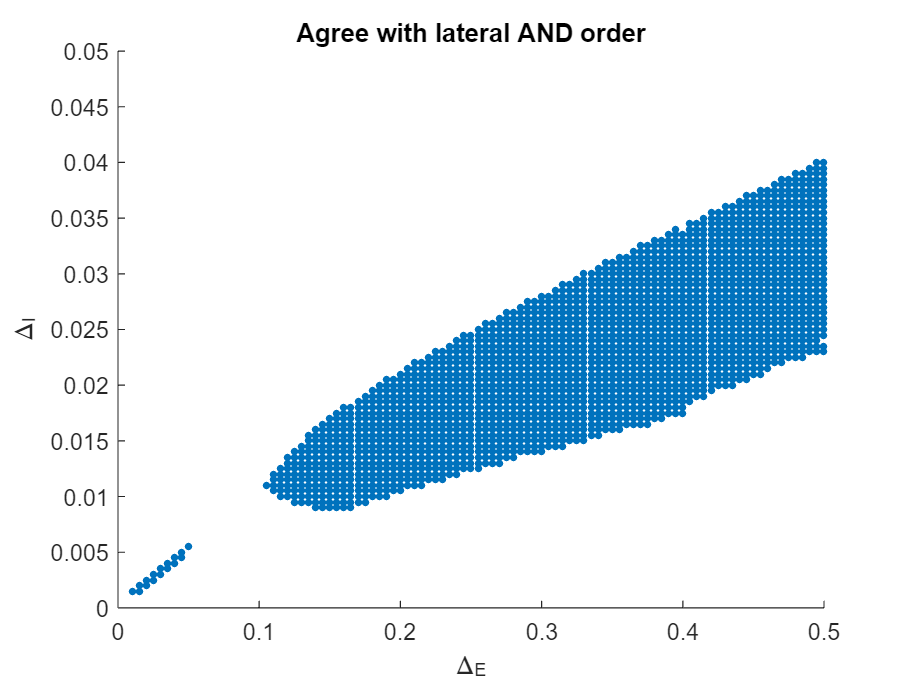

lat = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0
            lat(i,j) = 1;
        end
    end
end

roi = orderSheet & lat == 1;

sz = 10;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'filled',"MarkerFaceColor","#0072BD");
    hold on
end
xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Agree with lateral AND order");

## Agree with lateral OR order

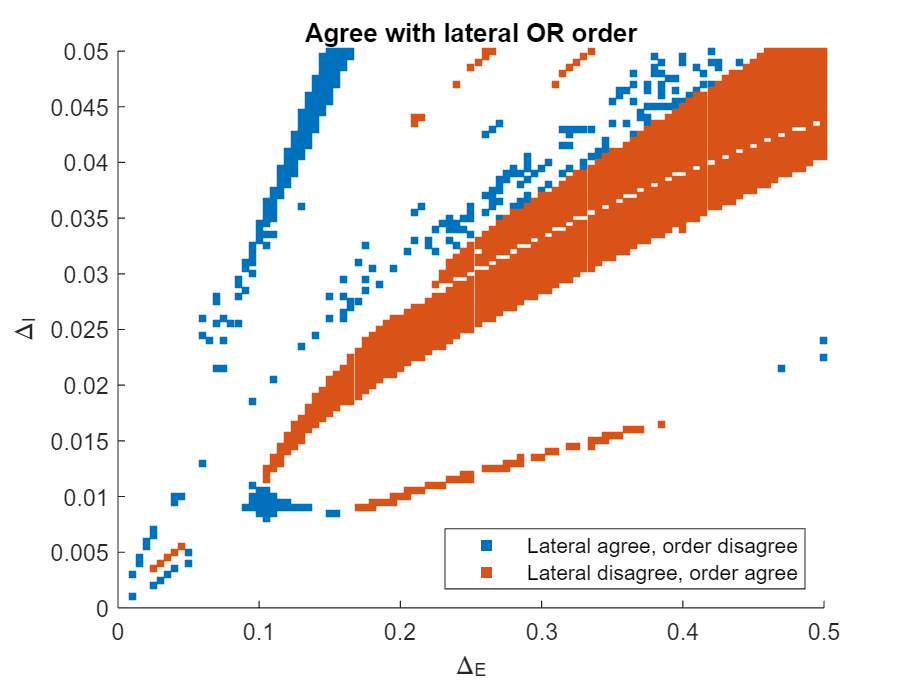

% lateral agree, order disagree (LaOd)
lat = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(lateralSheet(i,j,:)~=1) == 0
            lat(i,j) = 1;
        end
    end
end

LaOd = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lat(i,j) == 1 && orderSheet(i,j) == 0
            LaOd(i,j) = 1;
        end
    end
end
% lateral disagree, order agree (LdOa)
LdOa = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if lat(i,j) == 0 && orderSheet(i,j) == 1
            LdOa(i,j) = 1;
        end
    end
end

figure();
roi = LaOd == 1;
sz = 18;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s1 = scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end

roi = LdOa == 1;
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    s2 = scatter(x,y,sz,'square','filled',"MarkerFaceColor","#D95319");
    hold on
end

xlabel("\Delta_{E}");
ylabel("\Delta_{I}");
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
legend([s1 s2],["Lateral agree, order disagree","Lateral disagree, order agree"], ...
    "Location","southeast");
title("Agree with lateral OR order");

## oscillatory region

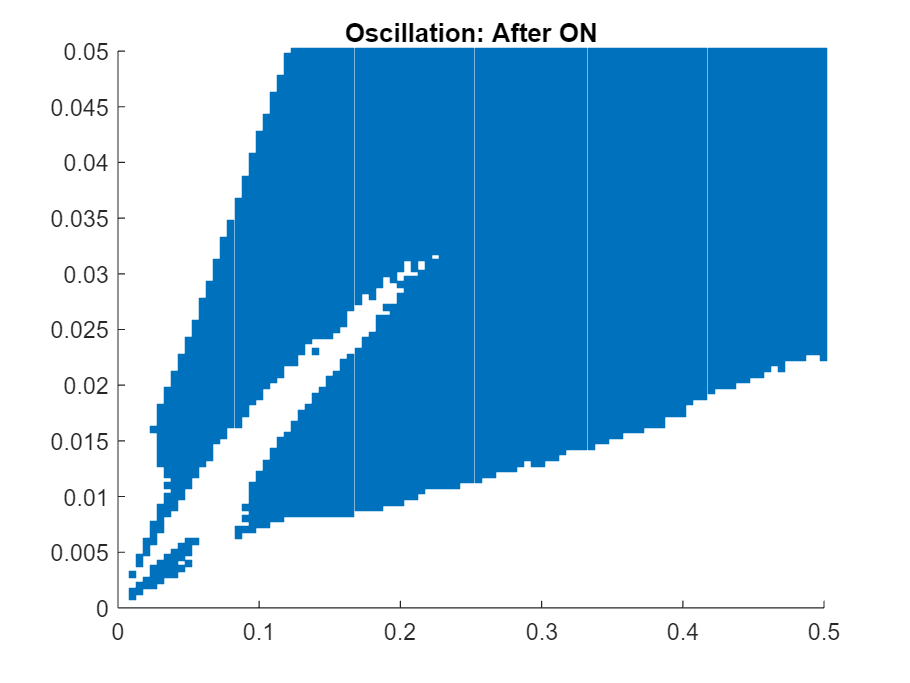

% is there 
load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
osci = zeros(steps,steps);
for i = 1:steps
    for j = 1:steps
        if sum(osciSheet(i,j,2,:)==1)==5
            osci(i,j) = 1;
        end
    end
end
roi = osci == 1;
figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Oscillation: After ON");

## Ratio

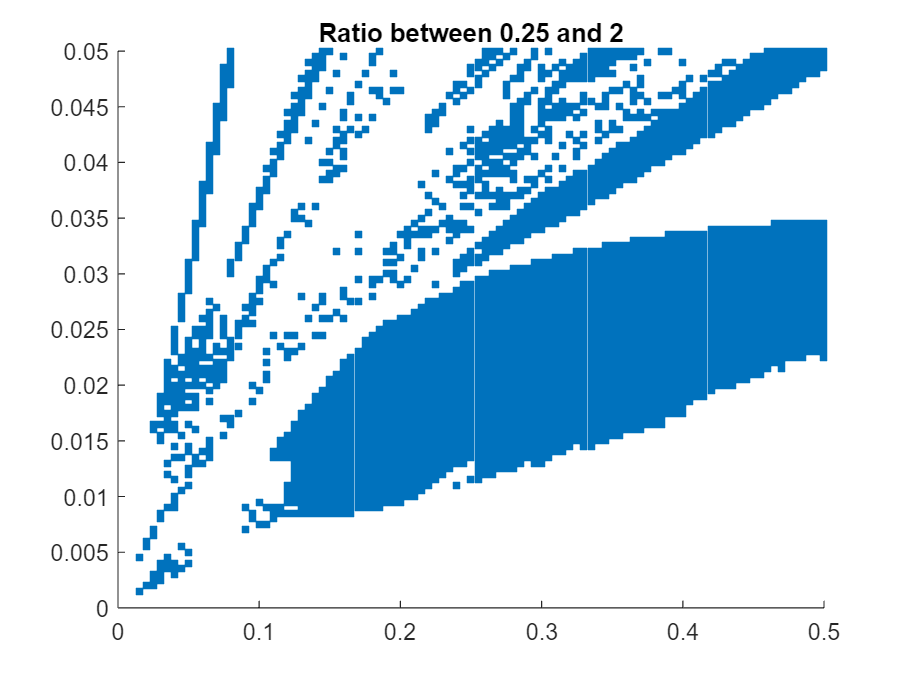

load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
down = 0.25; up = 2;
roi = ratioSheet > down & ratioSheet < up;
figure();
for i = 1:steps
    x = Delta_e(roi(steps+1-i,:));
    y = Delta_i(i)*ones(length(x),1);
    scatter(x,y,sz,'square','filled',"MarkerFaceColor","#0072BD");
    hold on
end
axis([Delta_e_start Delta_e_end Delta_i_start Delta_i_end]);
title("Ratio between "+num2str(down)+" and "+num2str(up));

## modify data

% load lateral\lateral_0_0.5_0_0.05_Iattn_0.02.mat
% 
% tmp = ratioSheet(:,:,1);
% ratioSheet = tmp;
% 
% filename = append('lateral_',num2str(Delta_e_start),'_',num2str(Delta_e_end),'_',...
%     num2str(Delta_i_start),'_',num2str(Delta_i_end), '_Iattn_', num2str(Iattn), '.mat');
% save(filename,'lateralSheet','orderSheet','gammaSheet','betaSheet','ratioSheet','osciSheet'); 